% --- CSV Paths ---
top_file    = '7062_860rpm_top_readings.csv';
bottom_file = '7062_860rpm_bottomreadings.csv';


% --- Read both files ---
fprintf('Reading TOP surface file...\n');

Reading TOP surface file...


data_top_full    = read_pressure_csv(top_file);      % Should be 16 tappings

Detected 16 columns per row
Successfully read 150 rows with 16 columns




fprintf('Reading BOTTOM surface file...\n');

Reading BOTTOM surface file...


data_bottom_full = read_pressure_csv(bottom_file);   % Should be 10 tappings

Detected 13 columns per row



% --- Verify dimensions ---
fprintf('Top data size: %d x %d\n', size(data_top_full));

Top data size: 150 x 16


fprintf('Bottom data size: %d x %d\n\n', size(data_bottom_full));

Bottom data size: 13 x 13




% --- Extract tappings ---
% Top surface: Tappings 1-15 (pure top)
% Tapping 16: benchmark (LE, physically bottom-side)
% Bottom surface: Tappings 16-25 (col 1 is tap 16 ref; cols 2-10 are taps 17-25)

tap_top_only    = data_top_full(:, 1:15);      % Tappings 1-15 (TE -> near LE)
tap_16          = data_top_full(:, 16);         % Tapping 16 (LE benchmark)

tap_bottom_only = data_bottom_full(:, 2:end);   % Tappings 17-25 (LE -> TE)

% --- Geometry: Chordwise positions (normalized x/c) ---
% Assume equal spacing; adjust if actual positions available
n_top_only    = size(tap_top_only, 2);           % Should be 15
n_bottom_only = size(tap_bottom_only, 2);        % Should be 9

fprintf('Top surface columns: %d (expected 15)\n', n_top_only);

Top surface columns: 15 (expected 15)


fprintf('Bottom surface columns: %d (expected 9)\n\n', n_bottom_only);

Bottom surface columns: 12 (expected 9)



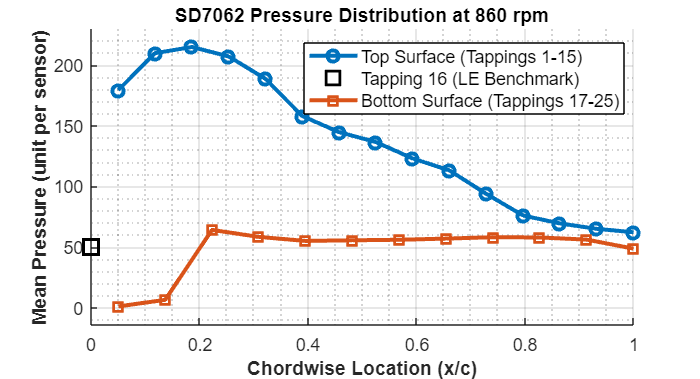


% Top: Tappings 1-15 from trailing edge (x/c=1) towards LE
x_top_only = linspace(1, 0.05, n_top_only);

% Tapping 16 at leading edge
x_16 = 0;

% Bottom: Tappings 17-25 from LE (x/c=0.05) towards trailing edge
x_bottom_only = linspace(0.05, 1, n_bottom_only);

% --- Compute time-averaged pressures ---
mean_top_only    = mean(tap_top_only, 1);
mean_16          = mean(tap_16, 1);
mean_bottom_only = mean(tap_bottom_only, 1);

% --- Create pressure distribution plot ---
figure('Position', [100 100 1200 650]);
hold on;

% Top surface line
plot(x_top_only, mean_top_only, '-o', 'LineWidth', 2.5, 'MarkerSize', 7, ...
    'Color', '#0072BD', 'DisplayName', 'Top Surface (Tappings 1-15)');

% Tapping 16 benchmark (LE)
plot(x_16, mean_16, 'ks', 'LineWidth', 2.5, 'MarkerSize', 12, ...
    'DisplayName', 'Tapping 16 (LE Benchmark)');

% Bottom surface line
plot(x_bottom_only, mean_bottom_only, '-s', 'LineWidth', 2.5, 'MarkerSize', 7, ...
    'Color', '#D95319', 'DisplayName', 'Bottom Surface (Tappings 17-25)');

% --- Formatting ---
xlabel('Chordwise Location (x/c)', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Mean Pressure (unit per sensor)', 'FontSize', 13, 'FontWeight', 'bold');
title('SD7062 Pressure Distribution at 860 rpm', 'FontSize', 15, 'FontWeight', 'bold');
legend('FontSize', 11, 'Location', 'best', 'EdgeColor', 'k');
grid on;
grid minor;
axis([0 1 min([mean_top_only, mean_16, mean_bottom_only])-15 ...
          max([mean_top_only, mean_16, mean_bottom_only])+15]);
set(gca, 'FontSize', 11);
hold off;


% --- Print tapping information ---
fprintf('\n========== PRESSURE DISTRIBUTION SUMMARY ==========\n');


========== PRESSURE DISTRIBUTION SUMMARY ==========


fprintf('Top Surface (Tappings 1-15):\n');

Top Surface (Tappings 1-15):


fprintf('  Mean: %.2f  |  Min: %.2f  |  Max: %.2f\n', ...
    mean(mean_top_only), min(mean_top_only), max(mean_top_only));

  Mean: 136.09  |  Min: 62.16  |  Max: 214.90


fprintf('\nTapping 16 (Benchmark, Leading Edge):\n');


Tapping 16 (Benchmark, Leading Edge):


fprintf('  Mean: %.2f\n', mean_16);

  Mean: 50.20


fprintf('\nBottom Surface (Tappings 17-25):\n');


Bottom Surface (Tappings 17-25):


fprintf('  Mean: %.2f  |  Min: %.2f  |  Max: %.2f\n', ...
    mean(mean_bottom_only), min(mean_bottom_only), max(mean_bottom_only));

  Mean: 47.84  |  Min: 1.02  |  Max: 64.11


fprintf('======================================================\n\n');



% --- Robust CSV parser with consistent column handling ---

function data = read_pressure_csv(filename)
    fid = fopen(filename, 'rt');
    data = [];
    row_count = 0;
    num_cols = []; % Will store the expected number of columns
    
    while ~feof(fid)
        line = fgetl(fid);
        if isempty(line) || ~ischar(line)
            continue;
        end
        
        % Skip separator lines (contain only dashes/dots/spaces)
        if all(ismember(line, '-. '))
            continue;
        end
        
        % Skip if line doesn't start with digit or minus
        if ~ismember(line(1), '0123456789-')
            continue;
        end
        
        % Split by hyphen
        parts = strsplit(line, '-');
        
        % Remove empty parts from split artifacts
        parts(cellfun(@isempty, parts)) = [];
        
        % First part is index; rest are pressures
        if numel(parts) >= 2
            pressures = [];
            for i = 2:numel(parts)
                val = str2double(parts{i});
                if ~isnan(val)
                    pressures = [pressures, val];
                end
            end
            
            % Ensure consistent number of columns
            if isempty(num_cols)
                num_cols = numel(pressures);
                fprintf('Detected %d columns per row\n', num_cols);
            end
            
            % Only add rows with correct column count
            if numel(pressures) == num_cols
                data = [data; pressures];
                row_count = row_count + 1;
            else
                fprintf('Warning: Row %d has %d columns (expected %d) - skipped\n', ...
                    row_count+1, numel(pressures), num_cols);
            end
        end
    end
    fclose(fid);
    fprintf('Successfully read %d rows with %d columns\n\n', row_count, num_cols);
end
